Load all relevant data:

% hpc
addpath(genpath('/proj/snic2022-5-384/users/x_albdv/reps/hca'));
addpath(genpath('/proj/snic2022-5-384/users/x_albdv/reps/discriminative_sequences'));
addpath(genpath('/proj/snic2022-5-384/users/x_albdv/reps/bargroupingprototype'));

% parpool('local');
dirName = '/proj/snic2022-5-384/users/x_albdv/data/discriminative/pyo';
% dirName = '/export/scratch/albertas/download_dump/S. pyogenes all data/onlyKymo/'; % folder with kymos
allTheoryFold = '/proj/dnadevdata/users/x_albdv/data/all/single/*.fasta';
refsNames = '/proj/snic2022-5-384/users/x_albdv/reps/discriminative_sequences/constants/pyo_theories.txt';
% refsNames = '/proj/snic2022-5-384/users/x_albdv/reps/discriminative_sequences/constants/pyo_t.txt';

% scratchget_
% dirName = '/proj/snic2022-5-384/users/x_albdv/data/discriminative/pyo/';
% refsNames = '/export/scratch/albertas/download_dump/S. pyogenes all data/ClosestTheories/refs_pyo.txt';
% allTheoryFold = '/export/scratch/albertas/download_dump/single/*.fasta';


savedir = '/proj/dnadevdata/users/x_albdv/data/PYO/output/';

[kymoStructs,barN,twoList,bG,expPar,fastaFileF] = load_kymo_data_from_fold(dirName, refsNames,allTheoryFold);


ans =

     4     4


ans =

     8     1


ans =

     4     3


ans =

     4     2


ans =

     4     1


ans =

     3     2


ans =

    10     1


ans =

     7     2


ans =

     7     3


ans =

     2     1


ans =

     7     1


ans =

    11     1


ans =

     6     3


ans =

    11     2


ans =

    11     3


ans =

     2     2


ans =

     8     2


ans =

     1     1


ans =

     2     3


ans =

     9     1


ans =

     5     1


ans =

     6     2


ans =

     6     1


ans =

     3     1

Kymographs nr  were removed because they do not have enough time-frames
Starting kymo alignment...
Kymographs nr  were removed because they do not have enough time-frames
Kymographs nr  were removed because they do not have enough time-frames
Starting kymo alignment...
Starting kymo alignment...
Kymographs nr  were removed because they do not have enough time-frames
Starting kymo alignment...
Kymographs nr  were removed because they do not have enough time-frames
Star

Binding model: pregenerate result positions

sets = [];
[cI,bI,compI2, parl,allCoefsFit,m2,mA] = get_pseudotheory_positions(bG, twoList,expPar, fastaFileF, sets);

Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Elapsed time is 4.659554 seconds.
Finished computing free concentrations
Elapsed time is 4.584461 seconds.
Finished computing free concentrations
Elapsed time is 4.502954 seconds.
Finished computing free concentrations
Elapsed time is 4.669372 seconds.
Finished computing free con

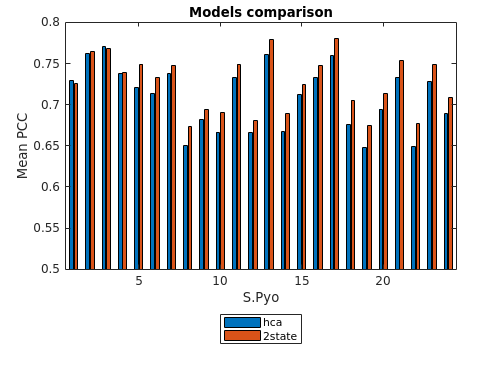

mtwo = cellfun(@(x) mean(x.maxcoef),cI,'UniformOutput',true);
% mA = cellfun(@(x) x.maxcoef(1),compI2,'UniformOutput',true);

% mA =cellfun(@(x) mean(cellfun(@(y) double(norminv(1-y.pval)),x).*cellfun(@(y) y.maxcoef(1),x)),compI2,'UniformOutput',true);

% score =cellfun(@(x) cellfun(@(y)  double(norminv(1-y.pval),x)>1.44,compI2,'UniformOutput',true);

 % stoufferScoresL = cellfun(@(x) double(norminv(1-x.pval)),compI2{expNr},'un',true);

plot_at_preference_model(bG,mA,mtwo)

Vary single parameter

expNr = 14;
sets.nuF = 0.08; sets.nF = 0.2; % pval params from assembly paper
sets.comparisonMethod = 'mass_pcc'; % could use C++ version or UCR ED as well
sets.w = nan;

sF = 0.9:0.01:1.1;
sigma = 0.68; % 68?
kY = 10; % constant yoyo
kN = 30; % constant netropsin
psf = 370; % psf
cN = 6; % concentration netropsin
cY = 0.02; % concentration yoyo
ligandLength = 4;
gcSF = 1;
isC = 1;
bound = [0 5];
[sigma_opt] = run_single_parameter(gcSF,isC,sigma,kN,psf,cY,cN,kY,ligandLength,fastaFileF,expNr,expPar,...
    bI,cI,bound,sets)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2   -6.877219e-01     0.000e+00     1.000e+00     0.000e+00     1.041e-02  
    1           4   -6.878231e-01     0.000e+00     1.000e+00     1.041e-02     9.057e-03  
    2           6   -6.881203e-01     0.000e+00     1.000e+00     4.529e-02     4.368e-03  
    3           8   -6.882374e-01     0.000e+00     1.000e+00     4.218e-02     1.366e-03  
    4          10   -6.882533e-01     0.000e+00     1.000e+00     1.920e-02     3.146e-04  
    5          12   -6.882543e-01     0.000e+00     1.000e+00     5.742e-03     3.032e-05  
    6          14   -6.882543e-01     0.000e+00     1.000e+00     6.126e-04     7.451e-07  
    7          16   -6.882543e-01     0.000e+00     1.000e+00     1.543e-05     1.490e-08  
    8          23   -6.882543e-01     0.000e+00     1.681e-01     5.085e-08     7.

sigma_opt = 0.8034


% parlist =  [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];

[ZZ] = run_single_parameter_any(gcSF,isC,sigma_opt,kN,psf,cY,cN,kY,ligandLength,fastaFileF,expNr,expPar,...
    bI,cI,[100 500],7,sets)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2   -6.882543e-01     0.000e+00     1.000e+00     0.000e+00     4.833e-05  
    1           4   -6.882543e-01     0.000e+00     1.000e+00     4.833e-05     4.833e-05  
    2           6   -6.882543e-01     0.000e+00     1.000e+00     2.417e-04     4.833e-05  
    3           8   -6.882544e-01     0.000e+00     1.000e+00     1.208e-03     4.833e-05  
    4          10   -6.882547e-01     0.000e+00     1.000e+00     6.042e-03     4.833e-05  
    5          12   -6.882561e-01     0.000e+00     1.000e+00     3.020e-02     4.830e-05  
    6          14   -6.882634e-01     0.000e+00     1.000e+00     1.509e-01     4.816e-05  
    7          16   -6.882994e-01     0.000e+00     1.000e+00     7.525e-01     4.745e-05  
    8          18   -6.884689e-01     0.000e+00     1.000e+00     3.707e+00     4.

ZZ = 435.1279

% 
[yoyoBindingProb] = get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
yoyofun = @(sigma)  get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
fun = @(xSv,ix1) -constfun_fit(yoyofun(xSv), cI{ix1},bI{ix1},fastaFileF{ix1},parl{ix1},sets);

vals = 0:0.01:4;
outv = zeros(1,numel(vals));
parfor i=1:numel(vals)
    outv(i) = fun(vals(i),expNr);
end

Analyzing and transferring files to the workers ...done.


The source code (/proj/snic2022-5-384/users/x_albdv/reps/discriminative_sequences/constants/binding_model_minimization.mlx) for the parfor-loop that is trying to execute on the worker could not be found.

Caused by:
    Unrecognized function or variable 'fun'.
    Worker unable to find file.
        Unrecognized function or variable 'fun'.





figure,plot(vals,outv,'x-')
hold on
% plot([yoyoBindingProb(idX) yoyoBindingProb(idX)],[min(outv) max(outv)],'red-')
title('Single par. fit')
xlabel('sigma')


fun = @(xSv,ix1) -constfun_fit(yoyofun(xSv), cI{ix1},bI{ix1},fastaFileF{ix1},parl{ix1},sets);

vals = 0:0.01:4;
outv = zeros(1,numel(vals));
parfor i=1:numel(vals)
    outv(i) = fun(vals(i),expNr);
end

% opt = optimValues.bestx;
% PRECALC FOR EACH
% opt = ZZ;

sets.nuF = 0.08; sets.nF = 0.2; % pval params from assembly paper
sets.comparisonMethod = 'mass_pcc'; % could use C++ version or UCR ED as well
sets.w = nan;

sF = 0.9:0.01:1.1;
sigma = 0.5; % 68?
kY = 10; % constant yoyo
kN = 30; % constant netropsin
psf = 370; % psf
cN = 6; % concentration netropsin
cY = 0.02; % concentration yoyo
pxSize = nmpx/nmbp; % pixel size
ligandLength = 4;
yoyo = 26;
netrospin = 0.4;
parchangeId = 5; % scaling factor for binding constants
par = 0.68;%
gcSF = 1;
isC = 1;

% initial yoyo binding prob
[yoyoBindingProb] = get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
yoyofun = @(kY,sigma)  get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);

mA = zeros(1,size(twoList,1));
sA = zeros(1,size(twoList,1));
mtwo= zeros(1,size(twoList,1));
sttwo= zeros(1,size(twoList,1));
mps= zeros(1,size(twoList,1));

% params for single set:
bI = {};
cI = {};
hc = {};
parl = {};
calcVals = zeros(size(twoList));
for expNr = 1:size(twoList,1);
    expNr
    barcodeGen = bG{expNr};
    nmbp = expPar{expNr}.nmbp;
    nmpx = expPar{expNr}.nmpx;
    [hcaSets,timestamp] = set_def();
    hcaSets.pixelWidthNm = nmpx;
    fastaFile = fastaFileF{expNr};
    hcaSets.folder{1} = fastaFileF{expNr} ;
    
    pxSize = nmpx/nmbp; % pixel size

    parlist = [gcSF,pxSize,nmpx,isC,sigma,kN,psf,cY,cN,kY,ligandLength];
    parlistcell = num2cell(parlist) ;
    
      [~,mid,~] = fileparts(hcaSets.folder{1} );
    delete(['seq_example',mid,'_',num2str(ligandLength) ,'.mat']);


    import Helper.run_comparison_fit;
    [cI{expNr}, rezI,   mtwo(expNr) , sttwo(expNr), sS,theoryStr,yoyoBindingProb,netropsinBindingConst] = ...
        run_comparison_fit(  barcodeGen,hcaSets.folder{1},parlistcell{:},parchangeId,par,sF,sets);

    mtwo = cellfun(@(x) mean(x.maxcoef),cI,'UniformOutput',true);

    import Core.rescale_barcode_data; % re-scale initial data
    [barGenRe] = rescale_barcode_data(barcodeGen,1,cI{expNr}.bestBarStretch);


    [mps(expNr)] = constfun_fit(yoyoBindingProb,cI{expNr},barGenRe,hcaSets.folder{1},parlistcell,sets);


    fun = @(kx,sx) -constfun_fit(yoyofun(kx,sx), cI{expNr},barGenRe,hcaSets.folder{1},parlistcell,sets);


    tol = 1e-11;
    options_all = optimoptions(@fmincon,'Display', 'iter', 'Algorithm', 'sqp', 'SpecifyObjectiveGradient',false, 'CheckGradient', false,  'OptimalityTolerance', tol, 'MaxFunctionEvaluations',20000 , 'StepTolerance', tol);
    
    xopt = [kY, sigma];

    lbounds = [zeros(1, length(xopt))];
    ubounds = [1000 10]; % no upper bounds on amplitudes

    [ZZ,FVAL,EXITFLAG,OUTPUT] = fmincon(@(x) fun(x(1),x(2)), xopt, [], [], [], [], lbounds, ubounds, [], options_all);
    calcVals(expNr,:) = ZZ;
end
    % hcaSets.pattern = 'binding_constant_rules.txt';
    % hcaSets.pattern = '4_model.txt';
    
    % import Core.run_hca_theory;
    % hcaTheory = arrayfun(@(x) run_hca_theory(hcaSets,x,netrospin),yoyo,'un',false);
    % [compI2,rezI2,m2,st2] = run_comp(barcodeGen,hcaTheory,nmbp,sets,sF);
    % 
    % stoufferScoresL = cellfun(@(x) double(norminv(1-x.pval)),compI2,'un',true);
    % 
    % mAll = cellfun(@(y) cellfun(@(x) x.maxcoef(1),y), rezI2,'un',false);
    % 
    % idx  = find(stoufferScoresL > 1.44);
    % mA(expNr) = mean(mAll{1}(idx));
    % sA(expNr) = std(mAll{1}(idx));
    % 
    % bI{expNr} = barcodeGen(idx);
    % parl{expNr} = parlistcell;
    % hc{expNr} = hcaSets.folder{1}
% end

% ix1 = 1;
[yoyoBindingProb] = get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);
yoyofun = @(sigma)  get_yoyo_prob(kN,kY, cN,cY, sigma, ligandLength);

fun = @(xSv,ix1) -constfun_fit(yoyofun(xSv), cI{ix1},bI{ix1},fastaFileF{ix1},parl{ix1},sets);

% fun(yoyoBindingProb,1)
% sum(lens([1 2 5 7 11 12 15 22]))

funM = @(x) -sqrt(sum(arrayfun(@(i) fun(x,i),1:24).^2))

funM = function_handle with value:
    @(x)-sqrt(sum(arrayfun(@(i)fun(x,i),1:24).^2))



tol = 1e-7;
options_all = optimoptions(@fmincon,'Display', 'iter', 'Algorithm', 'sqp', 'SpecifyObjectiveGradient',false, 'CheckGradient', false,  'OptimalityTolerance', tol, 'MaxFunctionEvaluations',20000 , 'StepTolerance', tol);

xopt = [0.4];

nvars = 1;
% no bounds ...
lbounds = [zeros(1, nvars)];
ubounds = [5*ones(1, nvars)]; % no upper bounds on amplitudes


[ZZ] = fmincon(@(x) funM(x), xopt, [], [], [], [], lbounds, ubounds, [], options_all);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           2   -4.088388e-01     0.000e+00     1.000e+00     0.000e+00     3.823e-02  
    1           4   -4.100346e-01     0.000e+00     1.000e+00     3.823e-02     2.350e-02  
    2           6   -4.106203e-01     0.000e+00     1.000e+00     6.099e-02     4.024e-03  
    3           8   -4.106391e-01     0.000e+00     1.000e+00

Updated fit

[cI,bI,compI2, parl,allCoefsFit,m2,mA] = get_pseudotheory_positions(bG, twoList,expPar, fastaFileF, sets,435,0.8);

Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Computing free concentrations
Elapsed time is 3.016652 seconds.
Finished computing free concentrations
Elapsed time is 2.993810 seconds.
Finished computing free concentrations
Elapsed time is 3.083749 seconds.
Finished computing free concentrations
Elapsed time is 3.064329 seconds.
Finished computing free con

mtwo = cellfun(@(x) mean(x.maxcoef),cI,'UniformOutput',true);

plot_at_preference_model(bG,mA,mtwo)


Validation datas